# **KINOVA Gen3 Manipulator Path Planning using STOMP**

This example shows how to plan a collision-free robot path from an initial to a desired end-effector pose using STOMP ([Stochastic trajectory optimization for motion planning](https://ieeexplore.ieee.org/document/5980280))[1].

## Robot Description and Poses

Load the KINOVA Gen3 rigid body tree (RBT) model.

robot_name = 'kinovaGen3';
robot = loadrobot(robot_name, 'DataFormat', 'column'); % Note there are different data formats for loading the robot (chosen in the 2nd argument)

Get the number of joints.

numJoints = numel(homeConfiguration(robot));

Specify the robot frame where the end-effector is attached.

endEffector = "EndEffector_Link"; 

Specify initial and desired end-effector poses. Use inverse kinematics (maps from pose to joint angles) to solve for the initial robot configuration given a desired pose.

% Initial end-effector pose
taskInit = trvec2tform([[0.4 0 0.2]])*axang2tform([0 1 0 pi]);

% Compute current robot joint configuration using inverse kinematics
ik = inverseKinematics('RigidBodyTree', robot);
ik.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];

currentRobotJConfig = ik(endEffector, taskInit, weights, robot.homeConfiguration);

% The IK solver respects joint limits, but for those joints with infinite
% range, they must be wrapped to a finite range on the interval [-pi, pi].
% Since the the other joints are already bounded within this range, it is
% sufficient to simply call wrapToPi on the entire robot configuration
% rather than only on the joints with infinite range.
currentRobotJConfig = wrapToPi(currentRobotJConfig);

% Final (desired) end-effector pose
taskFinal = trvec2tform([0.15 0.45 0.15])*axang2tform([0 1 0 pi]);  
anglesFinal = rotm2eul(taskFinal(1:3,1:3),'XYZ');
poseFinal = [taskFinal(1:3,4);anglesFinal']; % 6x1 vector for final pose: [x, y, z, phi, theta, psi]

% Final configuration
finalRobotJConfig = ik(endEffector, taskFinal, weights, currentRobotJConfig);
finalRobotJConfig = wrapToPi(finalRobotJConfig);

## Collision Meshes and Obstacles

MATLAB has its own collision world functions to check for and avoid collisions (e.g., collisionSphere, collisionBox, etc). Here, we follow the STOMP paper to set up the voxel world and using the signed Euclidean distance function for this purpose, which is a common practice in robotics perception, mapping, and collision avoidance. We shall still use the MATLAB built-in collision object functions to visualize the object for the convenience. See more details in the following helper functions.

helperCreateObstaclesKINOVA;

Visualize the robot at the initial configuration. You should see the obstacles in the environment as well.

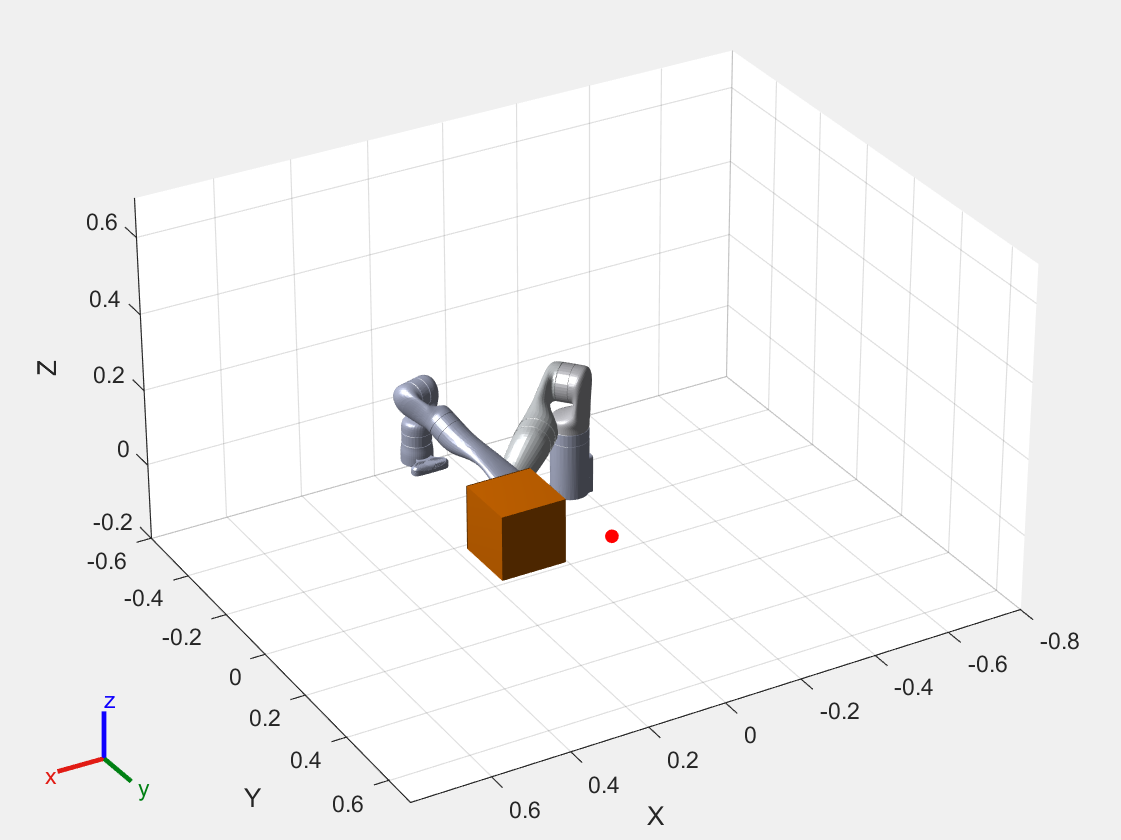

x0 = [currentRobotJConfig', zeros(1,numJoints)];
helperInitialVisualizerKINOVA;

Specify a safety distance away from the obstacles. This value is used in the inequality constraint function of the nonlinear MPC controller.

safetyDistance = 0.01; 

## Path Planning using STOMP

The following helper function contain the setup and execution of the STOMP algorithm for collision-avoidance planning.

历时 0.064124 秒。


Qtheta = 1.5092e+24

RAR = 60.9928

历时 0.063810 秒。


Qtheta = 1.5308e+24

RAR = 60.9945

历时 0.057928 秒。


Qtheta = 1.5091e+24

RAR = 60.9984

历时 0.058685 秒。


Qtheta = 1.5091e+24

RAR = 61.0075

历时 0.060895 秒。


Qtheta = 1.5091e+24

RAR = 61.0138

历时 0.059916 秒。


Qtheta = 1.5091e+24

RAR = 61.0143

历时 0.058903 秒。


Qtheta = 1.5091e+24

RAR = 61.0115

历时 0.064464 秒。


Qtheta = 1.5092e+24

RAR = 61.0029

历时 0.059691 秒。


Qtheta = 1.5090e+24

RAR = 61.0071

历时 0.056501 秒。


Qtheta = 1.5087e+24

RAR = 61.0124

历时 0.058697 秒。


Qtheta = 1.5087e+24

RAR = 61.0116

历时 0.061017 秒。


Qtheta = 1.5087e+24

RAR = 61.0287

历时 0.060297 秒。


Qtheta = 1.5084e+24

RAR = 61.0313

历时 0.056892 秒。


Qtheta = 1.5084e+24

RAR = 61.0194

历时 0.059385 秒。


Qtheta = 1.2420e+24

RAR = 61.0227

历时 0.060508 秒。


Qtheta = 1.5080e+24

RAR = 61.0149

历时 0.056143 秒。


Qtheta = 1.2415e+24

RAR = 61.0113

历时 0.058851 秒。


Qtheta = 1.2415e+24

RAR = 61.0154

历时 0.055623 秒。


Qtheta = 1.2420e+24

RAR = 61.0170

历时 0.056355 秒。


Qtheta = 1.2420e+24

RAR = 61.0238

历时 0.058857 秒。


Qtheta = 1.2420e+24

RAR = 61.0296

历时 0.057390 秒。


Qtheta = 1.2420e+24

RAR = 61.0335

历时 0.058848 秒。


Qtheta = 1.2415e+24

RAR = 61.0303

历时 0.057440 秒。


Qtheta = 1.2415e+24

RAR = 61.0349

历时 0.061015 秒。


Qtheta = 1.2415e+24

RAR = 61.0365

历时 0.055799 秒。


Qtheta = 1.2420e+24

RAR = 61.0412

历时 0.056977 秒。


Qtheta = 1.2420e+24

RAR = 61.0554

历时 0.057341 秒。


Qtheta = 1.2420e+24

RAR = 61.0590

历时 0.058499 秒。


Qtheta = 1.2413e+24

RAR = 61.0694

历时 0.057698 秒。


Qtheta = 1.2413e+24

RAR = 61.0702

历时 0.063643 秒。


Qtheta = 1.2389e+24

RAR = 61.0698

历时 0.057017 秒。


Qtheta = 1.2389e+24

RAR = 61.0666

历时 0.057651 秒。


Qtheta = 1.2389e+24

RAR = 61.0685

历时 0.058805 秒。


Qtheta = 1.2389e+24

RAR = 61.0676

历时 0.058582 秒。


Qtheta = 1.2389e+24

RAR = 61.0679

历时 0.059892 秒。


Qtheta = 1.2389e+24

RAR = 61.0643

历时 0.058973 秒。


Qtheta = 1.2389e+24

RAR = 61.0630

历时 0.057238 秒。


Qtheta = 1.2389e+24

RAR = 61.0657

历时 0.059399 秒。


Qtheta = 1.2389e+24

RAR = 61.0722

历时 0.055925 秒。


Qtheta = 1.2389e+24

RAR = 61.0709

历时 0.058662 秒。


Qtheta = 1.2390e+24

RAR = 61.0803

历时 0.059509 秒。


Qtheta = 1.2389e+24

RAR = 61.0777

历时 0.058628 秒。


Qtheta = 1.2390e+24

RAR = 61.0839

历时 0.057949 秒。


Qtheta = 1.2389e+24

RAR = 61.0846

历时 0.058357 秒。


Qtheta = 1.2390e+24

RAR = 61.0823

历时 0.058289 秒。


Qtheta = 1.2390e+24

RAR = 61.0759

历时 0.059580 秒。


Qtheta = 1.2390e+24

RAR = 61.0667

历时 0.055706 秒。


Qtheta = 1.2390e+24

RAR = 61.0723

历时 0.057192 秒。


Qtheta = 1.2390e+24

RAR = 61.0637

历时 0.058228 秒。


Qtheta = 1.2389e+24

RAR = 61.0552

历时 0.060372 秒。


Qtheta = 1.2389e+24

RAR = 61.0538

Maximum iteration (50) has reached.
STOMP Finished.


isTrajectoryInCollision = logical
   0


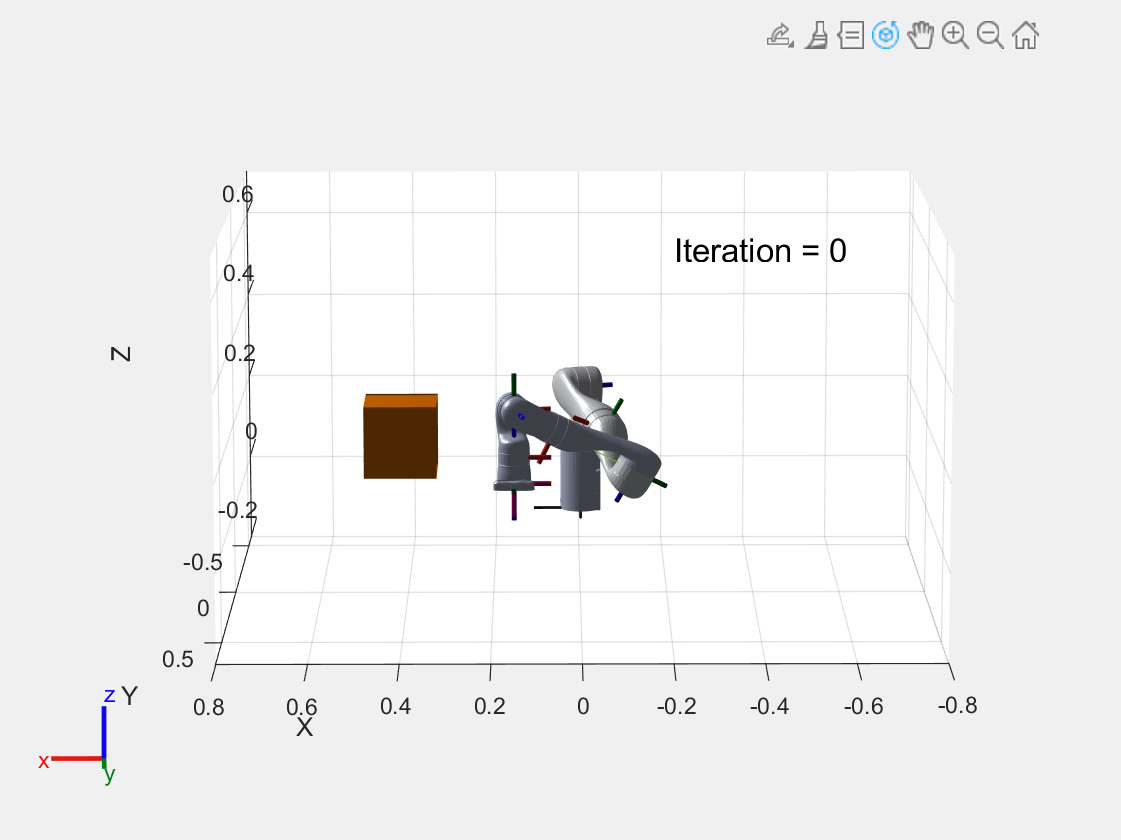

helperSTOMP;

[1] M. Kalakrishnan, S. Chitta, E. Theodorou, P. Pastor and S. Schaal, "STOMP: Stochastic trajectory optimization for motion planning," *2011 IEEE International Conference on Robotics and Automation*, 2011, pp. 4569-4574, doi: 10.1109/ICRA.2011.5980280.